# Matrix Computations

## Assignment1

### **Haoliang Sheng**

### Q1

#### (a)


$$-\epsilon u'' + au'' = f(x), 0 < x < 1\\
u(0) = \alpha, u(1) = \beta.$$


For $x \in [0,1]$, suppose that $x_j = jh, j = 0,1,...,n$, then $h = \frac{1}{n}$.

Using discrete approximations:


$$u'(x_i) \approx \frac{u(x_i+h)-u(x_i-h)}{2h} = \frac{u(x_{i+1})-u(x_{i-1})}{2h}\\
u''(x_i) \approx \frac{u(x_i+h)-2u(x_i)+u(x_i-h)}{h^2} = \frac{u(x_{i+1})-2u(x_i)+u(x_{i-1})}{h^2}.$$


For every $x_i$, we have $-\epsilon u''(x_i)+au'(x_i)=f(x_i)$, for $i=1,2,...,n-1
$.

Substituting these approximations for the derivatives into the differential equation, we obtain

$-\epsilon \frac{u(x_{i+1})-2u(x_i)+u(x_{i-1})}{h^2}+a\frac{u(x_{i+1})-u(x_{i-1})}{2h} \approx f(x_i)
$, for $i=1,2,...,n-1
$.

so, $-\epsilon \frac{u_{i+1}-2u_i+u_{i-1}}{h^2}+a\frac{u_{i+1}-u_{i-1}}{2h} \approx f_i
$, for $i=1,2,...,n-1
$.

It means, $\begin{cases} 
-\epsilon \frac{u_2-2u_1+u_0}{h^2}+a\frac{u_2-u_0}{2h}=f_1\\
-\epsilon \frac{u_3-2u_2+u_1}{h^2}+a\frac{u_3-u_1}{2h}=f_2\\
...\\
-\epsilon \frac{u_n-2u_{n-1}+u_{n-2}}{h^2}+a\frac{u_n-u_{n-2}}{2h}=f_{n-1}\\
\end{cases}$

Also, $\left(\frac{a}{2h}-\frac{\epsilon}{h^2}\right)u_{i+1}+\left(\frac{2\epsilon}{h^2}\right)u_i
+\left(-\frac{a}{2h}-\frac{\epsilon}{h^2}\right)u_{i-1} = f_i$.

Since $u(0) = \alpha, u(1) = \beta$, 

$\left\lbrack \begin{array}{cccccc}
\frac{2\epsilon }{h^2 } & \frac{a}{2h}-\frac{\epsilon }{h^2 } &  &  &  & 0\\
-\frac{a}{2h}-\frac{\epsilon }{h^2 } & \frac{2\epsilon }{h^2 } & \frac{a}{2h}-\frac{\epsilon }{h^2 } &  &  & \\
 & -\frac{a}{2h}-\frac{\epsilon }{h^2 } & \frac{2\epsilon }{h^2 } & \frac{a}{2h}-\frac{\epsilon }{h^2 } &  & \\
 &  & \ddots  & \ddots  & \ddots  & \\
 &  &  & -\frac{a}{2h}-\frac{\epsilon }{h^2 } & \frac{2\epsilon }{h^2 } & \frac{a}{2h}-\frac{\epsilon }{h^2 }\\
0 &  &  &  & -\frac{a}{2h}-\frac{\epsilon }{h^2 } & \frac{2\epsilon }{h^2 }
\end{array}\right\rbrack$ * $\left\lbrack \begin{array}{c}
u_1 \\
u_2 \\
u_3 \\
\vdots \\
u_{n-2} \\
u_{n-1} 
\end{array}\right\rbrack$ =$\;\left\lbrack \begin{array}{c}
f_1 -\left(-\frac{a}{2h}-\frac{\epsilon }{h^2 }\right)\alpha \\
f_2 \\
f_3 \\
\vdots \\
f_{n-2} \\
f_{n-1} -\left(\frac{a}{2h}-\frac{\epsilon }{h^2 }\right)\beta 
\end{array}\right\rbrack$

#### (b)

Since $f(x)=1,a=1,\alpha=\beta=0$,

Function becomes $-\epsilon u'' + u'' = 1, 0 < x < 1, u(0)=0,u(1)=0$

Also, $\left(\frac{1}{2h}-\frac{\epsilon}{h^2}\right)u_{i+1}+\left(\frac{2\epsilon}{h^2}\right)u_i
+\left(-\frac{1}{2h}-\frac{\epsilon}{h^2}\right)u_{i-1} = 1$

The exact solution is $U(x) =x-\frac{\exp\left(-\frac{1-x}{\epsilon}\right)-\exp\left(-\frac{1}{\epsilon}\right)}
{1-\exp\left(-\frac{1}{\epsilon}\right)}$.

Consider three different cases where the number of grid points are chosen as n = 25, 50 and 100. For each subdivision points change the choice of the diffusion coefficient $\epsilon$ = 1, 0.1 and 0.01

for n = [25 50 100]
    for epsilon = [1 0.1 0.01]        
        % Use function from M-file
        u = ode_solver(n,epsilon);

        % Display the results
        fprintf('For n = %d and epsilon = %.2f, u = \n', n, epsilon);
        disp(u');
    end
end

For n = 25 and epsilon = 1.00, u = 


    0.0163    0.0315    0.0458    0.0590    0.0712    0.0821    0.0920    0.1005    0.1078    0.1138    0.1184    0.1215    0.1231    0.1231    0.1216    0.1183    0.1132    0.1064    0.0976    0.0868    0.0739    0.0589    0.0416    0.0220



For n = 25 and epsilon = 0.10, u = 


    0.0400    0.0800    0.1199    0.1598    0.1997    0.2396    0.2794    0.3190    0.3585    0.3978    0.4366    0.4749    0.5123    0.5485    0.5827    0.6140    0.6410    0.6615    0.6722    0.6683    0.6425    0.5837    0.4756    0.2933



For n = 25 and epsilon = 0.01, u = 


    0.0400    0.0800    0.1200    0.1600    0.2000    0.2400    0.2800    0.3200    0.3600    0.4000    0.4400    0.4800    0.5200    0.5600    0.6000    0.6401    0.6798    0.7205    0.7586    0.8041    0.8277    0.9170    0.8089    1.2933



For n = 50 and epsilon = 1.00, u = 


    0.0082    0.0162    0.0240    0.0315    0.0388    0.0458    0.0525    0.0590    0.0652    0.0712    0.0768    0.0821    0.0872    0.0919    0.0964    0.1005    0.1043    0.1078    0.1110    0.1138    0.1162    0.1183    0.1201    0.1215    0.1225    0.1231    0.1233    0.1231    0.1225    0.1216    0.1201    0.1183    0.1160    0.1132    0.1100    0.1063    0.1022    0.0976    0.0924    0.0868    0.0806    0.0739    0.0667    0.0589    0.0505    0.0416    0.0321    0.0220    0.0113



For n = 50 and epsilon = 0.10, u = 


    0.0200    0.0400    0.0600    0.0799    0.0999    0.1199    0.1399    0.1598    0.1798    0.1997    0.2196    0.2396    0.2594    0.2793    0.2992    0.3190    0.3387    0.3584    0.3781    0.3976    0.4171    0.4364    0.4556    0.4746    0.4934    0.5119    0.5301    0.5479    0.5653    0.5820    0.5980    0.6130    0.6270    0.6397    0.6508    0.6598    0.6664    0.6700    0.6701    0.6656    0.6557    0.6392    0.6146    0.5800    0.5334    0.4719    0.3923    0.2906    0.1618



For n = 50 and epsilon = 0.01, u = 


    0.0200    0.0400    0.0600    0.0800    0.1000    0.1200    0.1400    0.1600    0.1800    0.2000    0.2200    0.2400    0.2600    0.2800    0.3000    0.3200    0.3400    0.3600    0.3800    0.4000    0.4200    0.4400    0.4600    0.4800    0.5000    0.5200    0.5400    0.5600    0.5800    0.6000    0.6200    0.6400    0.6600    0.6800    0.7000    0.7200    0.7400    0.7600    0.7800    0.8000    0.8200    0.8400    0.8600    0.8800    0.9000    0.9200    0.9400    0.9600    0.9800



For n = 100 and epsilon = 1.00, u = 


    0.0042    0.0082    0.0123    0.0162    0.0202    0.0240    0.0278    0.0315    0.0352    0.0388    0.0423    0.0458    0.0492    0.0525    0.0558    0.0590    0.0622    0.0652    0.0682    0.0711    0.0740    0.0768    0.0795    0.0821    0.0847    0.0872    0.0896    0.0919    0.0942    0.0964    0.0985    0.1005    0.1025    0.1043    0.1061    0.1078    0.1094    0.1110    0.1124    0.1138    0.1150    0.1162    0.1173    0.1183    0.1193    0.1201    0.1208    0.1215    0.1220    0.1225    0.1228    0.1231    0.1232    0.1233    0.1233    0.1231    0.1229    0.1225    0.1221    0.1215    0.1209    0.1201    0.1193    0.1183    0.1172    0.1160    0.1147    0.1132    0.1117    0.1100    0.1082    0.1063    0.1043    0.1022    0.0999    0.0976    0.0950    0.0924    0.0897    0.0868    0.0837    0.0806    0.0773    0.0739    0.0704    0.0667    0.0629    0.0589    0.0548    0.0505    0.0462    0.0416    0.0370    0.0321    0.0272    0.0220    0.0168    0.0113    0.0057



For n = 100 and epsilon = 0.10, u = 


    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0799    0.0899    0.0999    0.1099    0.1199    0.1299    0.1399    0.1498    0.1598    0.1698    0.1798    0.1897    0.1997    0.2097    0.2196    0.2296    0.2395    0.2495    0.2594    0.2694    0.2793    0.2892    0.2991    0.3090    0.3189    0.3288    0.3387    0.3485    0.3584    0.3682    0.3780    0.3878    0.3976    0.4073    0.4170    0.4267    0.4364    0.4460    0.4555    0.4651    0.4746    0.4840    0.4933    0.5026    0.5118    0.5210    0.5300    0.5390    0.5478    0.5565    0.5651    0.5735    0.5818    0.5899    0.5977    0.6054    0.6128    0.6199    0.6268    0.6333    0.6394    0.6451    0.6504    0.6552    0.6594    0.6630    0.6659    0.6681    0.6695    0.6700    0.6694    0.6678    0.6649    0.6607    0.6550    0.6476    0.6384    0.6272    0.6137    0.5978    0.5791    0.5575    0.5325    0.5038    0.4710    0.4337    0.3915    0.3437    0.2899    0.2294    0.1614    0.0852



For n = 100 and epsilon = 0.01, u = 


    0.0100    0.0200    0.0300    0.0400    0.0500    0.0600    0.0700    0.0800    0.0900    0.1000    0.1100    0.1200    0.1300    0.1400    0.1500    0.1600    0.1700    0.1800    0.1900    0.2000    0.2100    0.2200    0.2300    0.2400    0.2500    0.2600    0.2700    0.2800    0.2900    0.3000    0.3100    0.3200    0.3300    0.3400    0.3500    0.3600    0.3700    0.3800    0.3900    0.4000    0.4100    0.4200    0.4300    0.4400    0.4500    0.4600    0.4700    0.4800    0.4900    0.5000    0.5100    0.5200    0.5300    0.5400    0.5500    0.5600    0.5700    0.5800    0.5900    0.6000    0.6100    0.6200    0.6300    0.6400    0.6500    0.6600    0.6700    0.6800    0.6900    0.7000    0.7100    0.7200    0.7300    0.7400    0.7500    0.7600    0.7700    0.7800    0.7900    0.8000    0.8100    0.8200    0.8300    0.8400    0.8500    0.8600    0.8700    0.8800    0.8900    0.9000    0.9099    0.9198    0.9295    0.9386    0.9459    0.9477    0.9330    0.8689    0.6567



Plot the exact and approximate solutions on the same window for n = 50 and different values of $\epsilon$ = 1, 0.1, and 1.

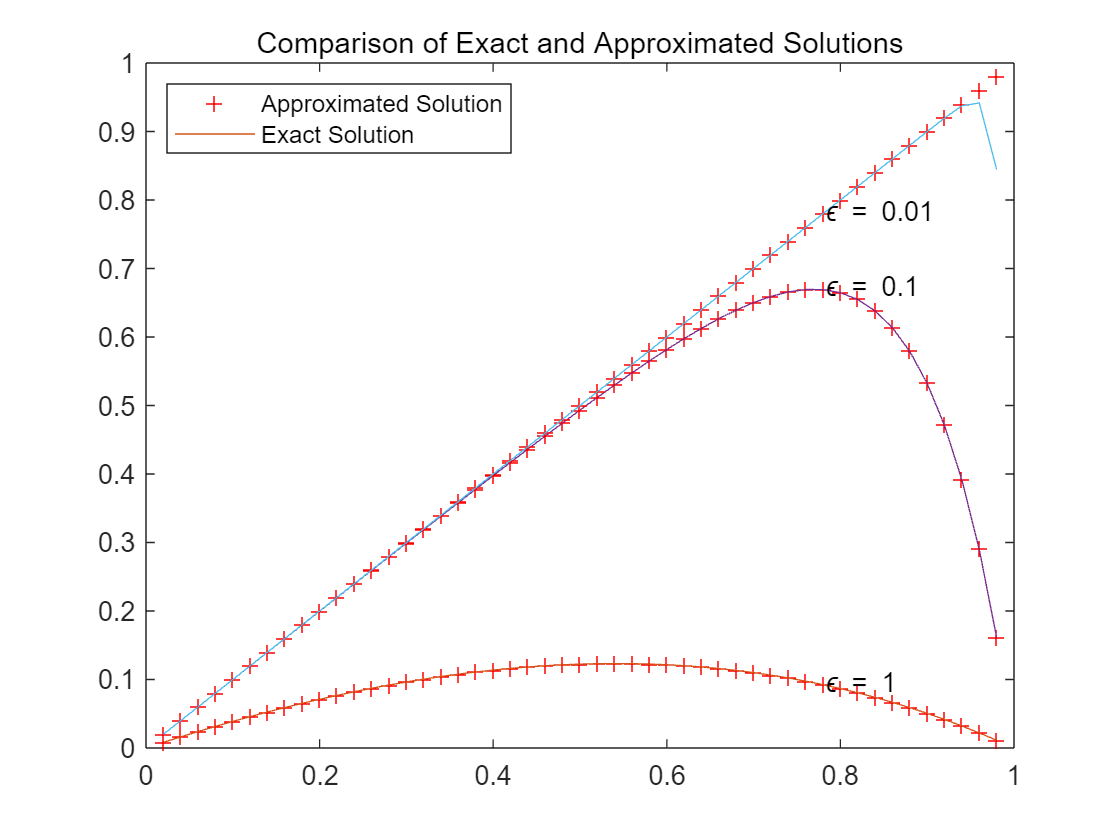

n = 50;
h = 1 / n; % Grid size

for epsilon = [1 0.1 0.01]
    % Use function from M-file
    u = ode_solver(n,epsilon);
    
    % Computing the exact solution
    t = linspace(h, 1-h, n-1);
    y = t - (exp(-(1-t)/epsilon) - exp(-1/epsilon)) / (1 - exp(-1/epsilon));
    
    % Plotting for comparison
    plot(t, u, 'r+'); hold on;
    plot(t, y, '-');

    % Adding epsilon value on the graph
    text(t(end-10), u(end-10), ['\epsilon = ', num2str(epsilon)]);
end

title('Comparison of Exact and Approximated Solutions');
legend('Approximated Solution', 'Exact Solution', 'Location', 'northwest');

When $\epsilon$ > 0.01, the approximate solution is consistent with the exact solution; when $\epsilon$ = 0.01, the approximate solution oscillates.

### Q2

matvectime

matrixsize = 500

time = 0.0156

matrixsize = 1000

time = 0.1250

ratio = 8

matrixsize = 2000

time = 0.5469

ratio = 4.3750

matrixsize = 4000

time = 2.7812

ratio = 5.0857

### Q3

Write a modified version of (1.3.5) for leading zeros for b.

Suppose that $b_1=b_2=...=b_k=0$

for $i = k+1, k+2, ..., n$

    for $i = k+1, k+2, ..., i-1$(not executed when i = k+1)

        
$$b_i=b_i-g_{ij}b_j$$


    if $g_{ii}=0$, set error flag, exit

    
$$b_i=b_i / g_{ii}$$


### Q4

#### 1.3.12

Write a nonrecursive algorithm in the spirit of (1.3.5).

G = [5 0 0;2 -4 0; 1 2 3];
b = [15;-2;10];
Y = forward_col(G, b)

Y =      3
     2
     1


#### 1.3.14

(a) Count the operations in (1.3.13) 


$$flops = \sum_{j=1}^n\sum_{i=j+1}^n 2 = 2\sum_{j=1}^n(n-j)=2(n-1+n-2+...+0)=n(n-1)\approx n^2$$


(b) Convince myself that the row- and column-oriented versions of forward substitution carry out exactly the same operations but not in the same order.

As the flops calculated before, flops_row = flops_column = $n^2$.

flops_row = $2\sum_{i=1}^n(i-1)= 2(0+1+...+n-1)$;

flops_column = $2\sum_{j=1}^n(n-j) = 2(n-1+n-2+...+0)$, they are not in the same order.

### Q5

Write an algorithm based on (1.4.13) and (1.14.14) , and calculate R of Example 1.4.18 using the Cholesky’s Algorithm.

A = [4 -2 4 2;-2 10 -2 -7;4 -2 8 4;2 -7 4 7];
R = cholesky(A)

R =      2    -1     2     1
     0     3     0    -2
     0     0     2     1
     0     0     0     1


### Q6

#### 1.4.21

$A=\left\lbrack \begin{array}{cccc}
16 & 4 & 8 & 4\\
4 & 10 & 8 & 4\\
8 & 8 & 12 & 10\\
4 & 4 & 10 & 12
\end{array}\right\rbrack$ and $b=\left\lbrack \begin{array}{c}
32\\
26\\
38\\
30
\end{array}\right\rbrack$.

(a) Use the Cholesky method to show A is positive definite and compute its Cholesky factor


$$\begin{array}{l}
r_{11} =\sqrt{a_{11} }=\sqrt{16}=4\\
r_{12} =\frac{a_{12} }{r_{11} }=\frac{4}{4}=1,r_{13} =\frac{8}{4}=2,r_{14} =\frac{4}{4}=1\\
r_{22} =\sqrt{a_{22} -r_{12}^2 }=\sqrt{10-1^2 }=3\\
r_{23} =\frac{a_{23} -r_{13} r_{12} }{r_{22} }=\frac{8-2}{3}=2,r_{24} =\frac{4-1}{3}=1\\
r_{33} =\sqrt{a_{33} -r_{13}^2 -r_{23}^2 }=\sqrt{12-2^2 -2^2 }=2\\
r_{34} =\frac{a_{34} -r_{14} r_{13} -r_{24} r_{23} }{r_{33} }=\frac{12-2^2 -2}{2}=3\\
r_{44} =\sqrt{a_{44} -r_{14}^2 -r_{24}^2 -r_{34}^2 }=\sqrt{12-1-1-3^2 }=1
\end{array}$$


so, $R=\left\lbrack \begin{array}{cccc}
4 & 1 & 2 & 1\\
0 & 3 & 2 & 1\\
0 & 0 & 2 & 3\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$.

R can be computed without error, A is positive definite.

(b) Use forward and backward substitution to solve the linear system.

Since ${\textrm{Ax}=R}^T R\;x=b$, define that Rx=y, then $R^T y=b$


$$\left\lbrack \begin{array}{cccc}
4 & 0 & 0 & 0\\
1 & 3 & 0 & 0\\
2 & 2 & 2 & 0\\
3 & 1 & 3 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
y_1 \\
y_2 \\
y_3 \\
y_4 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
32\\
26\\
38\\
30
\end{array}\right\rbrack$$



$$\begin{array}{l}
y_1 =\frac{b_1 }{g_{11} }=\frac{32}{4}=8\\
y_2 =\frac{\left(b_2 -g_{21} y_1 \right)}{g_{22} }=\frac{\left(26-8\right)}{3}=6\\
y_3 =\frac{\left(b_3 -g_{31} y_1 -g_{32} y_2 \right)}{g_{33} }=\frac{\left(38-2*8-2*6\right)}{2}=5\\
y_4 =\frac{\left(b_4 -g_{41} y_1 -g_{42} y_2 -g_{43} y_3 \right)}{g_{44} }=\left(30-8-6-3*5\right)=1
\end{array}$$


so, $y=\left\lbrack \begin{array}{c}
8\\
6\\
5\\
1
\end{array}\right\rbrack$, then Rx=y


$$\left\lbrack \begin{array}{cccc}
4 & 1 & 2 & 1\\
0 & 3 & 2 & 1\\
0 & 0 & 2 & 3\\
0 & 0 & 0 & 1
\end{array}\right\rbrack \left\lbrack \begin{array}{c}
x_1 \\
x_2 \\
x_3 \\
x_4 
\end{array}\right\rbrack =\left\lbrack \begin{array}{c}
8\\
6\\
5\\
1
\end{array}\right\rbrack$$



$$\begin{array}{l}
x_4 =\frac{y_4 }{g_{44} }=\frac{1}{1}=1\\
x_3 =\frac{\left(5-3\right)}{2}=1\\
x_2 =\frac{\left(6-2-1\right)}{3}=1\\
x_1 =\frac{\left(8-1-2-1\right)}{4}=1
\end{array}$$


so, $x=\left\lbrack \begin{array}{c}
1\\
1\\
1\\
1
\end{array}\right\rbrack$.

#### 1.4.22

Determine whether the matrices are positive definite.

A = [9 3 3;3 10 7;3 5 9];
try
    R = chol(A)
catch 
    warning('The matrix is not positive definite.');
end

R =      3     1     1
     0     3     2
     0     0     2


B = [4 2 6;2 2 5;6 5 29];
try
    R = chol(B)
catch 
    warning('The matrix is not positive definite.');
end

R =      2     1     3
     0     1     2
     0     0     4


C = [4 4 8;4 -4 1;8 1 6];
try
    R = chol(C)
catch 
    warning('The matrix is not positive definite.');
end

D = [1 1 1;1 2 2;1 2 1];
try
    R = chol(D)
catch 
    warning('The matrix is not positive definite.');
end

### Q7

Prove that n*n matrix has $n^3/3$ flops.

for $i=1,...,n$

    for $k=1,...,i-1$ (not executed when i=1)

        
$$a_{ii} = a_{ii}-a_{ki}^2$$


    if $a_{ii}\leq0$, set error flag

    $a_{ii} = \sqrt{a_{ii}}$ (this is $r_{ii}$)

    for $j=i+1,...,n$ (not executed when i=n)

        
$$a_{ij} = a_{ij}=a_{ki}a_{kj}$$


    $a_{ij}=a_{ij}/a_{ii}$ (this is $r_{ij}$)

We have $\sum_{i=1}^n i^2 = \frac{n^3}{3}+O(n^2)$.


$$
flops=\sum_{i=1}^n\sum_{k=1}^{i-1}2+\sum_{i=1}^n\sum_{j=i+1}^n\sum_{k=1}^{i-1}2\\
=2\sum_{i=1}^n(i-1)+2\sum_{i=1}^n(n-i)(i-1)\\
=n(n-1)+2n\sum_{i=1}^n(i-1)-2\sum_{i=1}^ni^2+2\sum_{i=1}^ni\\
=n^2-n+n^3-2\frac{n^3}{3}+O(n^2)\\
\approx \frac{n^3}{3}
$$


### Q8

Use outer-product formulation of Cholesky's method to calculate the Cholesky factor


$$\begin{array}{l}
B=\left\lbrack \begin{array}{ccc}
4 & 2 & 6\\
2 & 2 & 5\\
6 & 5 & 29
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{cc}
a_{11}  & b^T \\
b & \hat{A} 
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
r_{11}  & 0\\
s & {\hat{R} }^T 
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
r_{11}  & s^T \\
0 & \hat{R} 
\end{array}\right\rbrack 
\end{array}$$



$$\begin{array}{l}
r_{11} =\sqrt{a_{11} }=\sqrt{4}=2\\
s^T =r_{11}^{-1} b^T =\frac{1}{2}\left\lbrack \begin{array}{cc}
2 & 6
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
1 & 3
\end{array}\right\rbrack \\
\tilde{A} =\hat{A} -{\textrm{ss}}^T =\left\lbrack \begin{array}{cc}
2 & 5\\
5 & 29
\end{array}\right\rbrack -\left\lbrack \begin{array}{c}
1\\
3
\end{array}\right\rbrack \;\left\lbrack \begin{array}{cc}
1 & 3
\end{array}\right\rbrack \;=\left\lbrack \begin{array}{cc}
1 & 2\\
2 & 20
\end{array}\right\rbrack \\
\left\lbrack \begin{array}{cc}
1 & 2\\
2 & 20
\end{array}\right\rbrack =\left\lbrack \begin{array}{cc}
r_{22}  & 0\\
r_{23}  & r_{33} 
\end{array}\right\rbrack \left\lbrack \begin{array}{cc}
r_{22}  & r_{23} \\
0 & r_{33} 
\end{array}\right\rbrack \\
r_{22} =\sqrt{1}=1\\
r_{23} =\frac{2}{1}=2\\
r_{33} =\sqrt{20-2^2 }=4
\end{array}$$


so, $R=\left\lbrack \begin{array}{ccc}
2 & 1 & 3\\
0 & 1 & 2\\
0 & 0 & 4
\end{array}\right\rbrack$.

### Q9

Write an outer-product formulation of Cholesky algorithm, and impliment it in 1.4.22.

A = [9 3 3;3 10 7;3 5 9];
try
    R = cholesky_outerproduct(A)
catch 
    warning('The matrix is not positive definite.');
end

R =      3     1     1
     0     3     2
     0     0     2


B = [4 2 6;2 2 5;6 5 29];
try
    R = cholesky_outerproduct(B)
catch 
    warning('The matrix is not positive definite.');
end

R =      2     1     3
     0     1     2
     0     0     4


C = [4 4 8;4 -4 1;8 1 6];
try
    R = cholesky_outerproduct(C)
catch 
    warning('The matrix is not positive definite.');
end

D = [1 1 1;1 2 2;1 2 1];
try
    R = cholesky_outerproduct(D)
catch 
    warning('The matrix is not positive definite.');
end

### Q10

matcholtime

matrixsize = 500

time = 0.0156

matrixsize = 1000

time = 0.1250

ratio = 8

matrixsize = 2000

time = 0.5469

ratio = 4.3750

matrixsize = 4000

time = 4.2188

ratio = 7.7143

This matlab code uses data that that obeys a normal distribution to generate 500*500, 1000*1000, 2000*2000, 3000*3000 matrices, and testing the time they spent on the cholesky decomposition.

The ratio should be near to 8, because $\textrm{ratio}=\frac{n_2^3 }{n_1^3 }={\left(\frac{n_2 }{n_1 }\right)}^3 =2^3 =8$.